# **A Hitchhiker's Guide to fNIRS Data Analysis**

**DATA PREPROCESSING (Manuscript Section 3.2)**

Created by Franziska Klein

Commented by Mojtaba Soltanlou

Using Matlab 2021b

Last Updated 22/08/2023

This file is modified and commented: 30/10/2024, XW

Tested on: MATLAB R2024b

## What you need:

NIRS Brain AnalyzIR Toolbox: [https://github.com/huppertt/nirs-toolbox](https://github.com/huppertt/nirs-toolbox)

QT-NIRS: [https://github.com/lpollonini/qt-nirs](https://github.com/lpollonini/qt-nirs)

Note that if you continue from the previous script (standardization), you don’t need to close and clean the windows.

## Initializing Your working environment and load data

close all; clear all; clc;
% define your own path
"G:\fNIRS\Hitchhikers_Guide"

ans = "G:\fNIRS\Hitchhikers_Guide"

MAINPATH    = ans;
MAINPATH    = 'G:\fNIRS\Hitchhikers_Guide\';
PATHIN       = fullfile(MAINPATH, 'BIDS_DATA_IN');
PATHOUT      = fullfile(MAINPATH, 'DATA_OUT\preprocessed');
if ~exist(PATHOUT), mkdir(PATHOUT), end
addpath(genpath(MAINPATH))

cd (MAINPATH)

### Load Data

The*** .snirf*** data will be loaded here. If you have no ***.snirf*** file yet, go one step back and take a look at the ***BeginnersGuide_Standardisation.m*** script to convert your data first.

raw = nirs.io.loadDirectory(PATHIN, 'sub', {@nirs.io.loadSNIRF}, '.snirf');

Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-05\nirs\sub-05_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-06\nirs\sub-06_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-07\nirs\sub-07_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-08\nirs\sub-08_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-09\nirs\sub-09_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-10\nirs\sub-10_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-11\nirs\sub-11_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-12\nirs\sub-12_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS\Hitchhikers_Guide\BIDS_DATA_IN\sub-13\nirs\sub-13_task-motor_run-1_fnirs.snirf
Loading SNIRF file: G:\fNIRS

### Signal Quality Assessment via QT-NIRS (Manuscript Section 3.2.2)

- It is important to check the signal quality before starting data analysis to see how the recording went.

- The signal quality assessment is performed by using the ***QT-NIRS ***toolbox. This toolbox must be downloaded, added to the MATLAB-path and some files need to be copied to the respective folders in the nirs-toolbox *(cf. https://github.com/lpollonini/qt-nirs/wiki)*. Quality assessment is based on the scalp-coupling index (***sciThreshold; default = 0.8***) and the peak spectral power (***job.pspThreshold; empirical default = 0.1*** should not be changed; Pollonini et al., 2014, 2016). Moreover, with ***job.qThreshold (default = 0.75)*** a generalminimal quality criterion can be defined. ***job.fCut = [0.5 2.5]*** are the default cut-off frequencies for separating the heartbeat from thesignal. Note that regarding the Shannon-Nyquist theorem the sampling rate should be higher than twice the higher frequency of interest (***i.e., 2*2.5 Hz = 5 Hz***), if the sampling frequency is lower, the cut-off should be reduced accordingly.

- Be aware that these values are based on previous studies in WEIRD (Western, Educated, Industrialized, Rich, and Democratic) adult samples. Therefore, they may not be suitable for infants, children, clinical, and non-WEIRD populations. You may still use it for your study after adjusting those values (i.e., mostly reducing the thresholds) because it is one of the rare existing toolboxes that allows  measurable and replicable quality check rather than visual inspection which might be influenced by several factors such as the researcher’s bias and experience.

- Note that for data derived from **Hitachi ETG-4000**, the **QT-NIRS** doesn't work well.

- When using the QT with **Hitachi ETG-4000** data, it will probably remove most of the channels.

job = nirs.modules.QT;
% The threshold is a value between 0 and 1. The default is 0.75, but we set it to a lower bar of 0.65.
job.qThreshold = 0.65;
%The threshold for scalp coupling index (e.g., good quality if SCI >= threshold). The default is 0.8, but 
% we set it to a lower bar of 0.6.
job.sciThreshold = 0.6;
% PSP threshold, empirically set at 0.1.
job.pspThreshold = 0.1;
ScansQuality = job.run(raw);

Scan 1 of 15 processed.
Scan 2 of 15 processed.
Scan 3 of 15 processed.
Scan 4 of 15 processed.
Scan 5 of 15 processed.
Scan 6 of 15 processed.
Scan 7 of 15 processed.
Scan 8 of 15 processed.
Scan 9 of 15 processed.
Scan 10 of 15 processed.
Scan 11 of 15 processed.
Scan 12 of 15 processed.
Scan 13 of 15 processed.
Scan 14 of 15 processed.
Scan 15 of 15 processed.


Here are further possible options and their default values that you may want to adjust based on your needs.

% % This min and max frequency cutoff is used to isolate the cardiac pulsation.
% job.fCut = [0.5 2.5];
% % The default length of the window to partition the signal is 5 s.
% job.windowSec = 5;
% % As a default, there will be no overlap between the selected time windows.
% job.windowOverlap = 0;
% % The binary array maps the selected two wavelengths to compute the SCI.
% job.lambda_mask = 'all';
% % This function indicates working with optical density data.
% job.dodFlag = 0;
% %This function indicates whether to start or not the QT-NIRS GUI.
% job.guiFlag = 0;
% % This binary mask (or the keyword 'all') indicates the conditions for computing the periods of interest.
% job.condMask = 'resting';

**Draw Signal Quality Assessment**

You can further plot scalp coupling index (*sci*), peak spectral power (*psp*), and signal quality (*sci* & *psp*) using the below functions.

% ScansQuality.drawGroup('sci');
% ScansQuality.drawGroup('psp');
% ScansQuality.drawGroup('sq');

## PREPROCESSING 

### Conversion to optical density changes (dOD) (Manuscript Section 3.2.3)

This function converts the raw light intensity to changes in optical density using the formula $dOD = - log(\frac{raw}{raw_{avg}})$ with natural logarithm.

job = nirs.modules.OpticalDensity;
dOD = job.run(raw); 
 

Using following code line, you can inspect the difference between a good and a poor performancing channel.

sub_idx = 11;    % index for to be plotted subject
good_chan = 10;  % index for good channel
bad_chan = 2;    % index for bad channel
chancompare(dOD, sub_idx, good_chan, bad_chan)

Scan 1 of 1 processed.


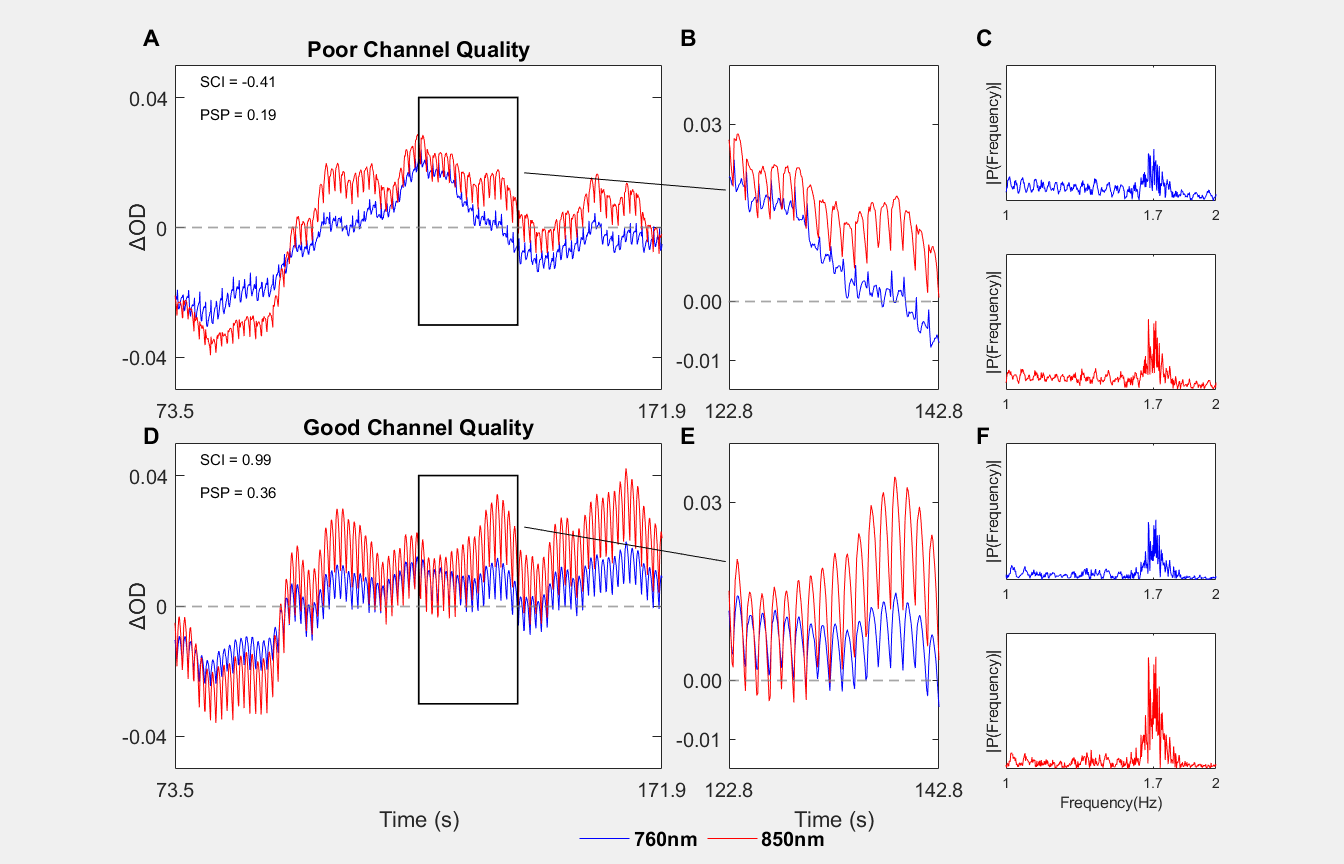

set(gcf,'Visible','on')    % force figure window

Otherwise you can also use plotting functions in the nirs-toolbox.

% % To visually inspect dOD data of all subjects, use the below function.
% dOD.draw;
% % To visually inspect dOD data of a specific subject (e.g., subject 6), use the below function.
% dOD(6).draw;

% % This function will show the GUI to see the optical density data.
% nirs.viz.TimeSeriesViewer (dOD)

### Motion Artifact Correction (Manuscript Section 3.2.4)

Here, we apply a motion artifact (MA) correction on the dOD data by using tha TDDR algorithm (`Fishburn et al., 2019`) implemented in this toolbox. No more MA corrections implemented in this toolbox. It is also possible to skip this step if you are planning to use the AR-ILS GLM for your analysis because it handles MAs (`cf. Barker et al., 2013`).

job = nirs.modules.TDDR;
dOD_MC = job.run(dOD); 
 

Using following code block, you can compare the data with and without motion artifact correction.

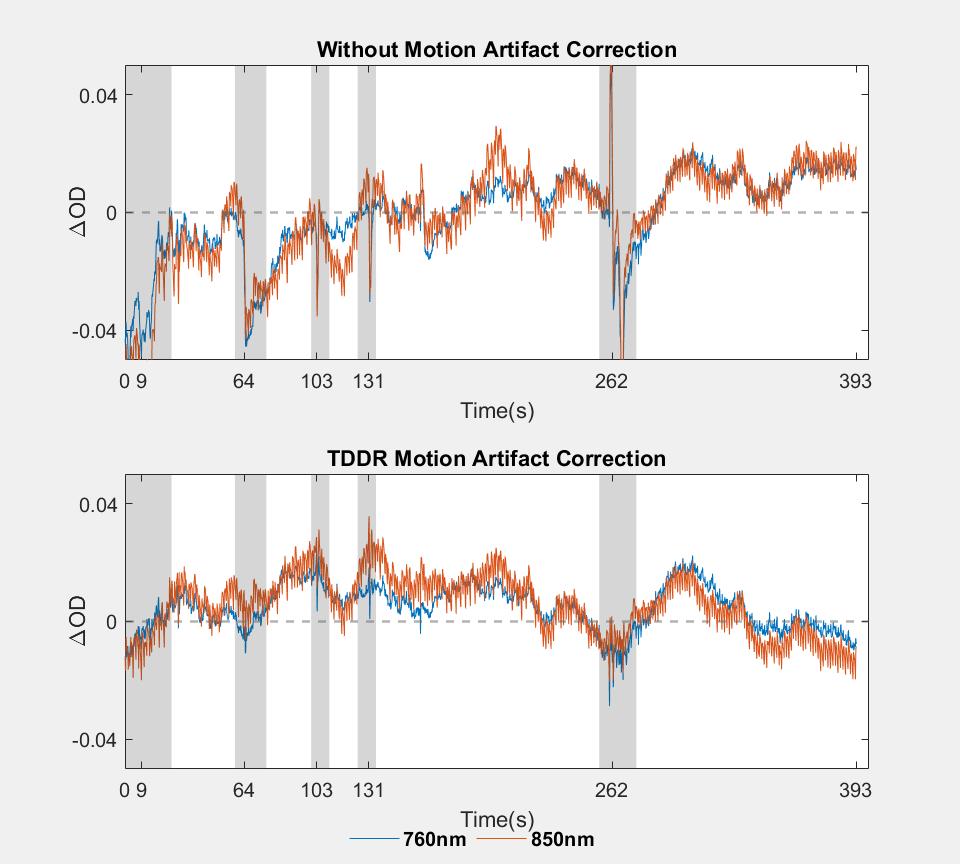

Nr_sub = 15;
Nr_chan = 10;
time_vec = dOD(Nr_sub).time;
plot_range = 1:4000;    % in samples
% find obvious motion artifact and then mark the time periods
zoom_in_idx = {
    (time_vec >= 0 & time_vec < 25), ...
    (time_vec >= 59 & time_vec < 76), ...
    (time_vec >= 100 & time_vec < 110), ...
    (time_vec >= 125 & time_vec < 135), ...
    (time_vec >= 255 & time_vec < 275)
};

MAplot_dOD(dOD, dOD_MC,Nr_sub, Nr_chan, plot_range, zoom_in_idx)
set(gcf,'Visible','on')    % force figure window

Still, you can use toolbox function to inspect the data alternatively.

% % To visually inspect MA corrected data of all subjects, use the below function.
% dOD_MC.draw;
% % To visually inspect MA corrected data of a specific subject (e.g., subject 6), use the below function.
% dOD_MC(6).draw;

% % This function shows the GUI to see the data after motion correction.
% nirs.viz.TimeSeriesViewer (dOD_MC);

There's another possiblity to do the motion artifact correction, by using HOMER2 Toolbox.

% % ~~~~~~~~~~~~~~~~~ %
% % HOMER2 functions
% % ~~~~~~~~~~~~~~~~~ %
% % Homer2 is another toolbox for fNIRS data analysis that is compatible with this toolbox. You can use any 
% % Homer2 motion correction function by using the Run_HOMER2 module. 
% % You need to download (https://homer-fnirs.org/download/) and add it to the MATLAB path.
% 
% job = nirs.modules.Run_HOMER2;
% % Next is the motion artifact detection using the following parameters. You can either use these 
% % default values, or adjust them based on your needs.
% job.fcn = 'hmrMotionArtifactByChannel';
% job.vars.tMotion = .5;
% job.vars.tMask = 2;
% job.vars.std_thresh = 14;
% job.vars.amp_thresh = .2;
% % You need to keep the detected artifacts to be corrected in the next step in Homer2.
% job.keepoutputs = true;
% 
% % Next you need to add on a job to remove artifacts that have been detected above.
% job = nirs.modules.Run_HOMER2(job);
% job.fcn = 'hmrMotionCorrectSpline';
% % Next is to use the 'tIncCh' output from the previous function.
% job.vars.tInc = '<linked>:output-tIncCh'; 
% job.vars.p = .99;
% job.keepoutputs = true;
% 
% % Now you can run both jobs.
% dOD_MC_homer = job.run(dOD);

### Conversion to Hemoglobin Concentration Changes (dHbX) (Manuscript Section 3.2.3)

The next step is to convert optical density changes to hemoglobin concentration changes using the **modified Beer Lambert law**.

Instead of using the differential pathlength factor (**DPF**), the default in this function is using the partial pathlength factor (**PPF**). PPF is the DPF corrected by a value called differential volume factor (**PVF**; `cf. Whitemann et al., 2018`). You can change to DPFs by simply adding them to

`job.PPF = [DPF_wavelength1, DPF_wavelength2];`

% To apply the modified Beer Lambert law, the default PPF = 0.1.
job = nirs.modules.BeerLambertLaw;

Here are further possible options and their default values that you may want to adjust based on your needs.

% The default partial pathlength factor is calculated by DPF/PVF.
% job.PPF = 5 / 50;

dHbX = job.run(dOD_MC);
 

Now you have already worked with raw, dOD and dHbX data. Using following code block may help you visually inspect the differences among them.

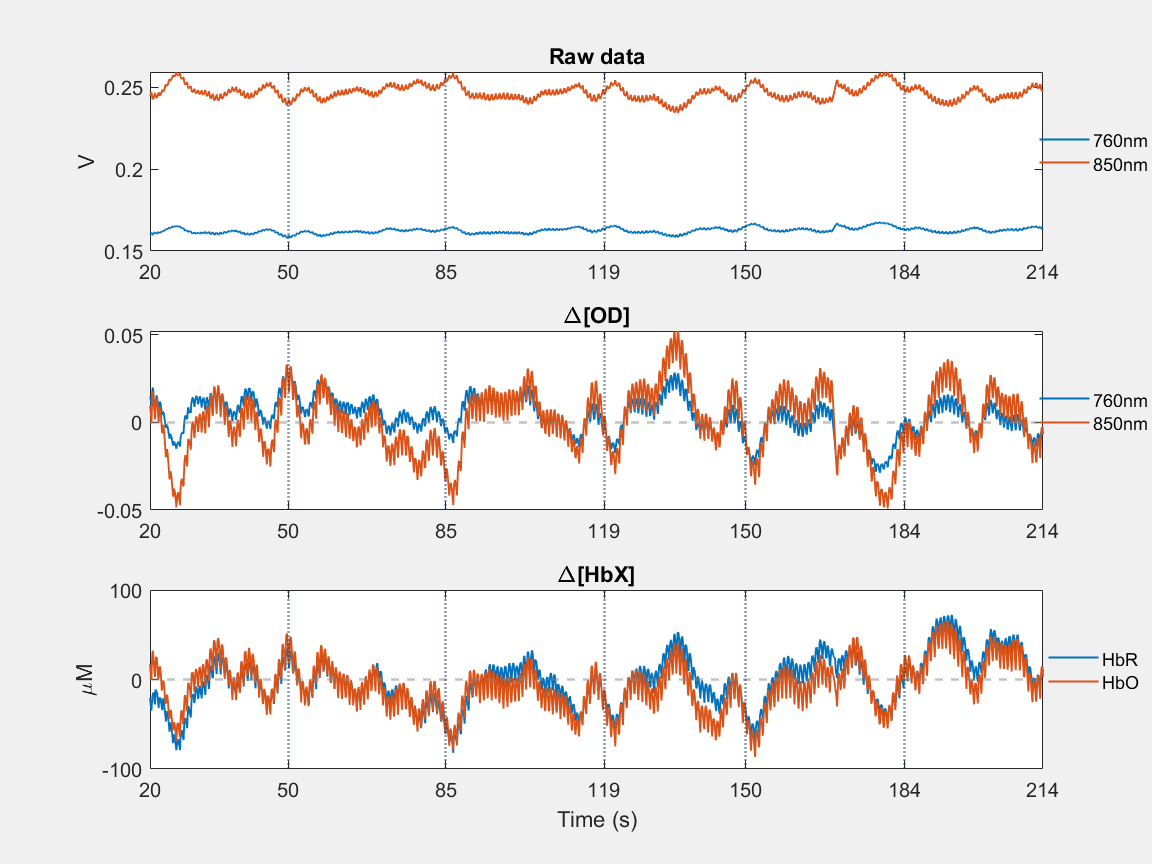

Nr_sub = 5;
chan2plot = 13;

dataplot_single_chan(raw, dOD, dHbX, Nr_sub,chan2plot)
set(gcf,'Visible','on')    % force figure window

Next code line will visualize all channels from those three kinds of data.

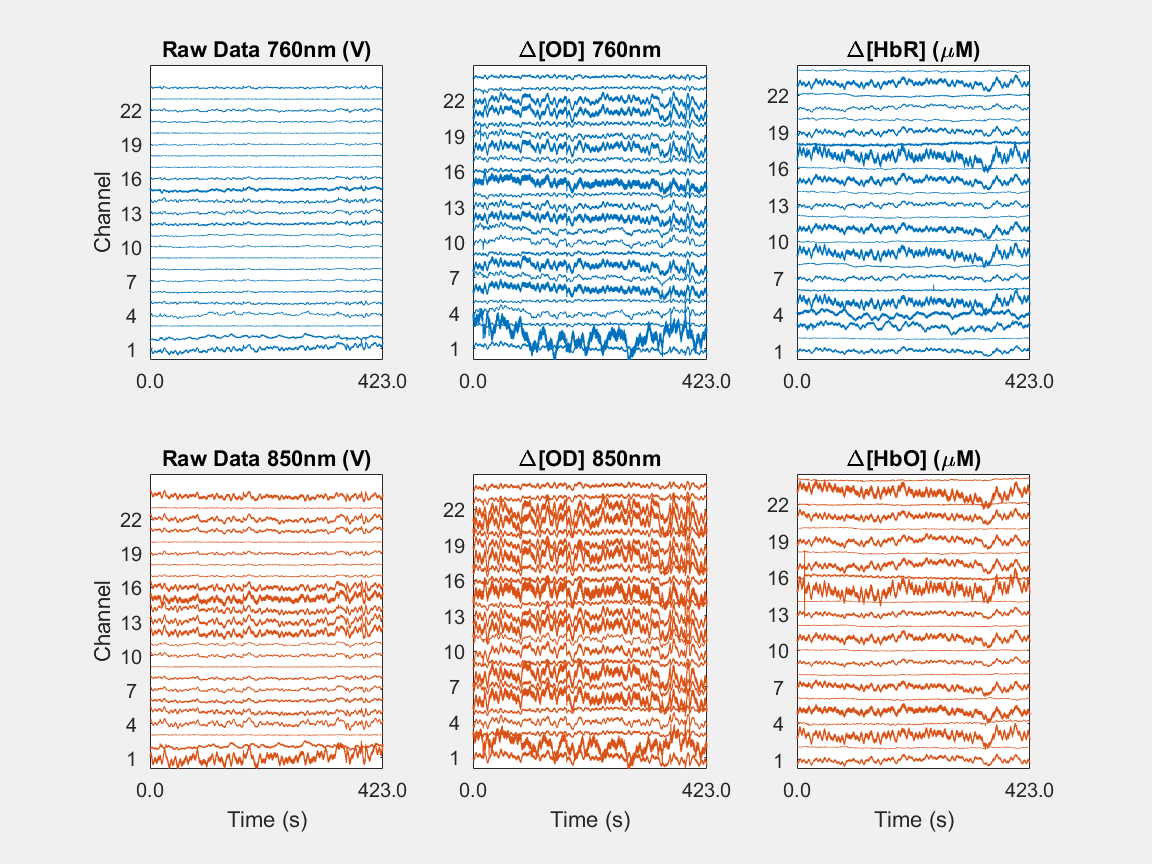

dataplot(raw, dOD, dHbX,Nr_sub)
set(gcf,'Visible','on')    % force figure window

### Temporal Filtering (Manuscript Section 3.2.5)

If you want to apply a temporal filter to remove physiological confounds (e.g., cardiac oscillations (~1 Hz), respiration (~0.3 Hz), Mayer waves (~0.1 Hz), etc.), you can choose between MATLAB **IIR** and **FIR** filters, otherwise you can simply skip this preprocessing step. 

Make sure that you do not filter out your task frequency. Here is the formula that you can use to find the task frequency or frequency of interest in your study that you want to keep.

$\frac{1}{t_{task} + t_{rest}}$  $$t_{task}$$ and $t_{rest}$ are the duration in second

These are MATLAB built-in functions and need to be applied on the data directly as there is no filter module in the NIRS toolbox. 

To find the best boundaries for your frequency filter, you can plot the power spectrum density (**PSD**) of your signal. The PSD plot will show you the main oscillations in your signal. Alternatively, you can follow the suggested boundaries in the literature, as we use here.

Furthermore, to apply the IIR Butterworth filter, you need to set the order. The filter orders are usually low for IIR filters, otherwise they get unstable `(cf. Pinti et al., 2019)`.

To apply the FIR filter, you need to set the order as well. The filter orders could be as high as 1000 to be effective, as recommended by `Pinti et al. (2019)`, though you need to be cautious using this high-order filter. Additionally, data length needs to be at least 3*filter order in combination with zero-phase filter. If your data doesn’t meet this prerequisite, instead of reducing the filter order consider using an IIR filter.

% High pass and low pass cutoff frequencies, respectively, 
% as recommended by Pinti et al. (2019).
hpf = 0.015;
lpf = 0.09;

cutoff = [hpf,lpf];
IIR_order = 2;
FIR_order = 1000;
filter_type = 'band';

% Using the following function to filter the dHbX data
[Hb_iir_filtered, Hb_fir_filtered] = dhbxFilter(dHbX, cutoff,...
    IIR_order, FIR_order,filter_type)

Hb_iir_filtered = 15×1 Data array with properties:
    description
    data
    probe
    time
    Fm
    auxillary
    stimulus
    demographics
    Fs


Hb_fir_filtered = 15×1 Data array with properties:
    description
    data
    probe
    time
    Fm
    auxillary
    stimulus
    demographics
    Fs


Note that if for some reasons, a causal filter (i.e., filter() function) is anticipated, it is not recommended to use it in combination with such a high filter order, because this would result in a huge delay. For instance, the delay of filter order*(1/2) -> 1000*(1/2) = 500 data points; so, with a sampling rate of 10 Hz, this means a delay of 50 s!

**Visualization of Filters**

Following we can observe what have the filters done to the data.

 
% values to define
Nr_Sub = 5;
Nr_chan = 13;
data = dHbX(Nr_Sub);
IIR_order = 2;
FIR_order = 1000;
lcut = 0.09; % Hz
hcut = 0.015; % Hz

We can firstly see what are the differences among the low-pass, high-pass and band-pass IIR-filters.

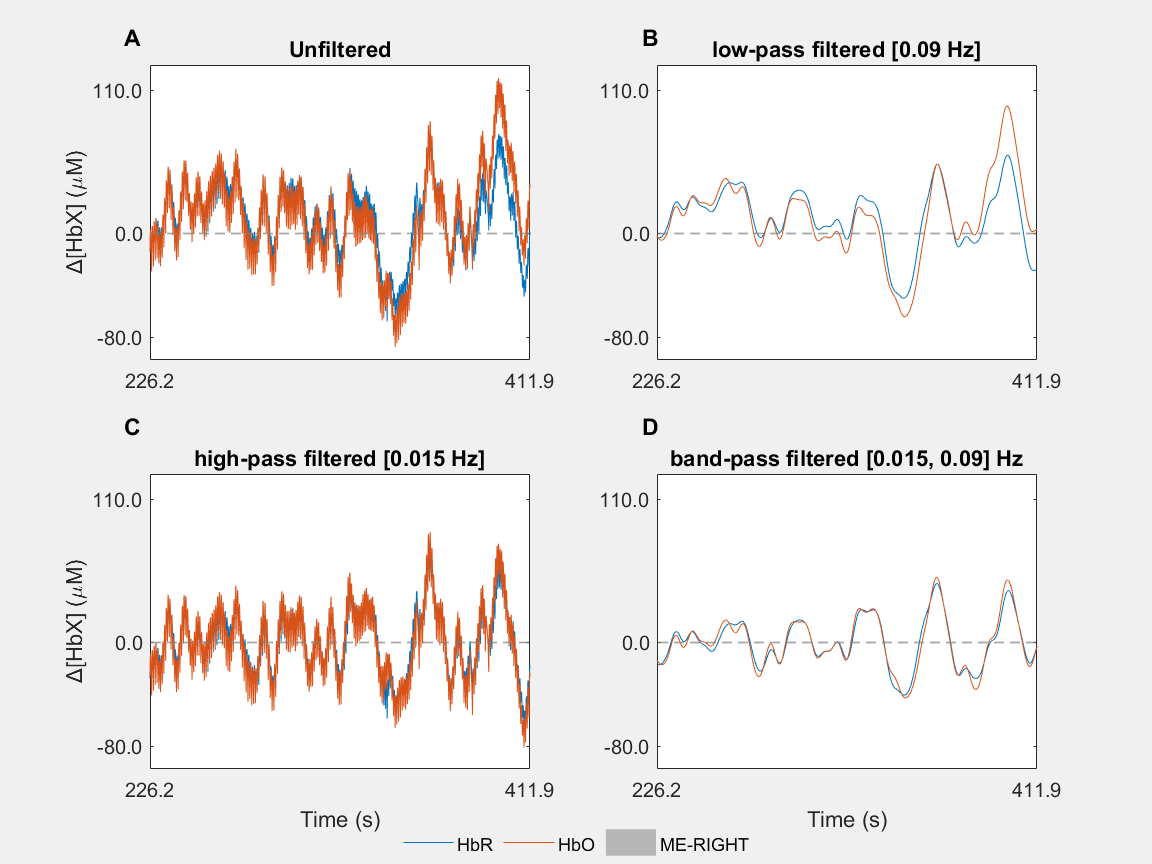

plot_type = 'IIR';   % 'IIR_FIR': IIR vs. FIR, 'IIR': all filters
IIR_plot(dHbX, Nr_Sub, Nr_chan, IIR_order, FIR_order, lcut, hcut, plot_type)
set(gcf,'Visible','on')    % force figure window

Then we further compare the band-pass IIR- and FIR-filters, in order to check whether they totally differ to each other. 

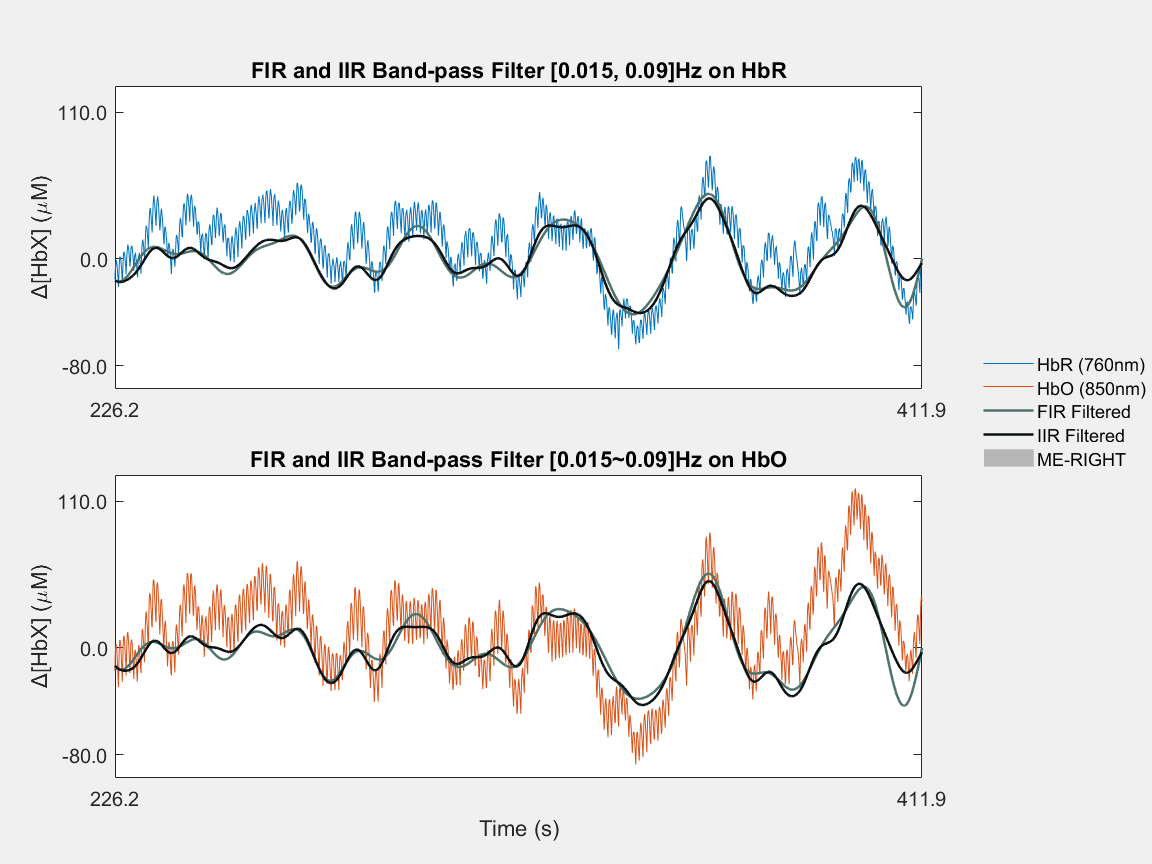

plot_type = 'IIR_FIR';   % 'IIR_FIR': IIR vs. FIR, 'IIR': all filters
IIR_plot(dHbX, Nr_Sub, Nr_chan, IIR_order, FIR_order, lcut, hcut, plot_type)
set(gcf,'Visible','on')    % force figure window

### Channel Pruning Based on QT-NIRS Results

This step is based on the channel quality assessment step that we performed earlier using the QT-NIRS. As the data of the channels with poor quality are replaced with NaNs, this step should be applied after filtering because the filter functions do not work on NaNs.

% TO DO: CHANNEL PRUNING IN LATER STEP, BECAUSE FOR SOME REASONS GLM
% DOESN'T WORK ANYMORE
Hb_pruned = Hb_iir_filtered;
for i = 1:length(raw)
   Hb_iir_filtered(i) = Hb_iir_filtered(i).sorted({'source', 'detector', 'type'});
   idxBadCh           = find(ScansQuality(i).qMats.MeasListAct == 0);

   Hb_pruned(i).data(:, idxBadCh) = nan;
   bad_chans(i) = (length(idxBadCh)/size(Hb_pruned(i).data, 2))*100;

   fprintf('Scan %i: #BadChannels: %i', i, length(idxBadCh)/2);
   fprintf(', i.e., %i%% of the channels will be pruned\n', round(bad_chans(i)));
end

Scan 1: #BadChannels: 3

, i.e., 13% of the channels will be pruned


Scan 2: #BadChannels: 2

, i.e., 8% of the channels will be pruned


Scan 3: #BadChannels: 0

, i.e., 0% of the channels will be pruned


Scan 4: #BadChannels: 0

, i.e., 0% of the channels will be pruned


Scan 5: #BadChannels: 2

, i.e., 8% of the channels will be pruned


Scan 6: #BadChannels: 2

, i.e., 8% of the channels will be pruned


Scan 7: #BadChannels: 6

, i.e., 25% of the channels will be pruned


Scan 8: #BadChannels: 6

, i.e., 25% of the channels will be pruned


Scan 9: #BadChannels: 3

, i.e., 13% of the channels will be pruned


Scan 10: #BadChannels: 1

, i.e., 4% of the channels will be pruned


Scan 11: #BadChannels: 1

, i.e., 4% of the channels will be pruned


Scan 12: #BadChannels: 0

, i.e., 0% of the channels will be pruned


Scan 13: #BadChannels: 6

, i.e., 25% of the channels will be pruned


Scan 14: #BadChannels: 2

, i.e., 8% of the channels will be pruned


Scan 15: #BadChannels: 1

, i.e., 4% of the channels will be pruned


### Add SDC Info (Manuscript Section 3.2.6)

We now add the information about the short distance channels (SDCs) to the data, if we have it. This step results in an additional column in the raw.probe.link structure (raw.probe.link.ShortSeparation), containing a 1 if the channel is a SDC and a 0 if it is a long-distance channel.

Note that the default value for this process is 15 mm  but you need to check raw.probe.distances for the distances stored in your data set.

Note that this step could be added at any other steps as well.

% If data is pruned, initialize the data
Hb_iir_filtered = Hb_pruned;

job = nirs.modules.LabelShortSeperation;
% You need to define maximally allowed SDC distance in mm, which is 10 mm here.
job.max_distance = 10;
Hb_iir_filtered  = job.run(Hb_iir_filtered);
 

### Systemic Activity Correction with GLM  (Manuscript Section 3.2.6)

To further clean the data a GLM will be run including only SDC as regressors if you have recorded it. To avoid removing any task-related activity, task-related information (i.e., stimulus info) has to be removed.

res = Hb_iir_filtered;
job = nirs.modules.DiscardStims;
job.listOfStims = {'ME_LEFT', 'ME_RIGHT'};
res = job.run(res);

% Add SDCs as regressors to the GLM filter.
% TO DO: include this in cleaning GLM module (other TO DO) and make
% separate version (because of normalization!)
job = nirs.modules.AddShortSeperationRegressors;
job.scICA = false;
res = job.run(res);

% run cleaning GLM
job = nirs.modules.AR_IRLS;
% Add a constant to correct the trend or drift.
job.trend_func = @(t) nirs.design.trend.constant(t);

% Get residuals as cleaned data.
job_resid = advanced.nirs.modules.GLMResiduals;
job_resid.GLMjob = job;

hb_residuals = job_resid.run(res);

Finished   15 of   15.


Hb_SDCcor = Hb_iir_filtered;
for s = 1:size(res, 1)
     % This will replace data with cleaned data.
    Hb_SDCcor(s).data = hb_residuals(s).data;
end

% using short distance Channels as regressors in GLM to clean the data
hb_residuals = GLM_Corr(Hb_iir_filtered);

Finished   15 of   15.



% initializing Hb_SDCcor
Hb_SDCcor = Hb_iir_filtered;
% This will replace data with cleaned data.

Hb_SDCcor = arrayfun(@(x) setfield(x, 'data', hb_residuals), Hb_SDCcor);
 

Alternatively, if you have not recorded SDC, you can subtract the average across all channels from each channel to correct for non-specific changes `Saager & Berger (2005)`. This is a common correction method in EEG researchHowever, you may need to be careful with this method because if you still have huge signal changes in some non-ROIs, you may lose those changes of interest in your ROIs.

% [Hb_SSR, ~, ~] = nirs.modules.SSR(Hb_pruned, 'noSDC');  

### Add HbT and HbDiff

This function offers the option to add $d[HbT]$ (i.e., $d[HbO] + d[HbR]

$) and $d[HbDiff]$ (i.e., $d[HbO] - d[HbR]$) to the data. You can skip this step if you are not interested in total Hb and the difference between `HbO` and `HbR` in your analysis.

job = nirs.modules.Calculate_HbT_HbDiff; 
HbT_HbDiff_SDCcor = job.run(Hb_SDCcor); 
 

## Save Data

% You can now save the results of the above steps.
save(fullfile(PATHOUT, 'data_preprocessed.mat'), 'Hb_SDCcor', 'dHbX', 'HbT_HbDiff_SDCcor',  'ScansQuality');
 